# Generación de trayectorias en el espacio cartesiano (TASK-SPACE)

En este ejemplo se van a generar trayectorias en el espacio cartesiano. Se va a dibujar un circulo con un robot planar de 2gdl y con un robot manipulador IRB120.

## Generación de trayectorias con robot planar de 2 gdl

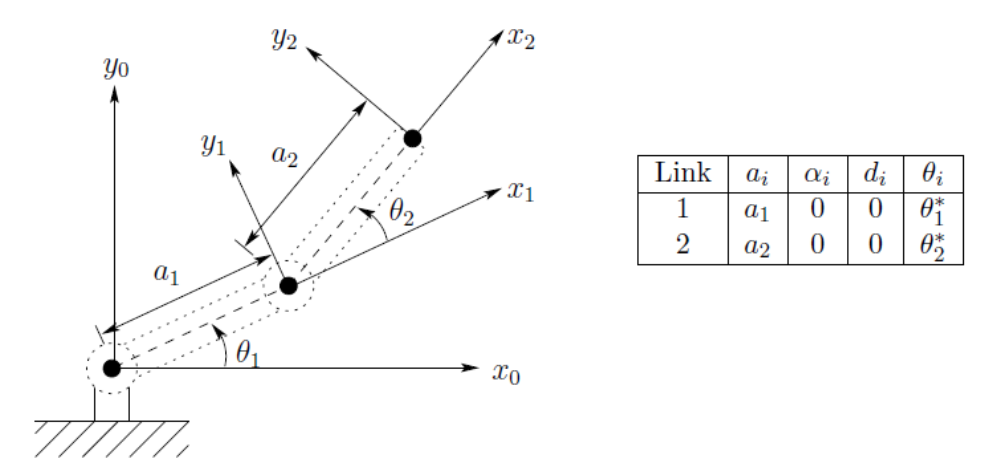

**Creamos el robot planar de 2gdl**

Parámetros geométricos

clear 
close all

a1 = 0.3;        
a2 = 0.2;           
theta1_min = 0;         
theta1_max = pi/2;
theta1= pi/8; 
theta2_min = 0;
theta2_max = pi;
theta2 = pi/4;

dhparams = [a1  0   0  theta1;
            a2 	0   0  theta2];


Creación del rigidbodytree

robot = rigidBodyTree ('DataFormat', 'column');
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
jnt1.HomePosition = theta1;
jnt1.PositionLimits = [theta1_min, theta1_max];
body1.Joint = jnt1;
addBody(robot,body1,'base')

body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh');
jnt2.HomePosition = theta2;
jnt2.PositionLimits = [theta2_min, theta2_max];
body2.Joint = jnt2;
addBody(robot,body2,'body1')

showdetails(robot)

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


**Definir la trayectoria circular robot planar de 2 gdl **

Defina un círculo que se trazará en el transcurso de 10 segundos. Este círculo está en el plano con un radio de 0,1

t = (0:0.2:10)'; % Time
count = length(t);
center = [0.1 0.3 0];
radius = 0.1;
theta = t*(2*pi/t(end));
points = center + radius*[cos(theta) sin(theta) zeros(size(theta))]; %[x, y, z]

**Definición del espacio de trabajo del robot**

step = 0.1;
vTheta1 = theta1_min:step:theta1_max; % all possible theta1 values
vTheta2 = theta2_min:step:theta2_max; % all possible theta2 values

[THETA1,THETA2] = meshgrid(vTheta1,vTheta2); % generate grid of angle values

X = a1 * cos(THETA1) + a2 * cos(THETA1 + THETA2); % compute x coordinates
Y = a1 * sin(THETA1) + a2 * sin(THETA1 + THETA2); % compute y coordinates

data1 = [X(:) Y(:) THETA1(:)]; % create x-y-theta1 dataset
data2 = [X(:) Y(:) THETA2(:)]; % create x-y-theta2 dataset


**Visualización de la trayectoria y del espacio de trabajo del robot**

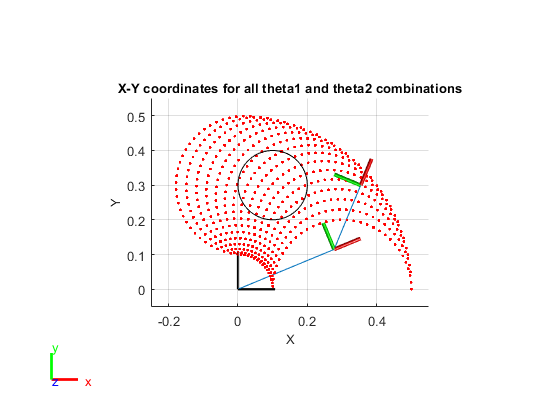

figure
show(robot); 
hold all;
view (2)
ax = gca; 
ax.Projection = 'orthographic';  
plot(X(:),Y(:),'r.'); 
plot(points(:,1),points(:,2),'k')
axis equal;
xlabel('X','fontsize',10)
ylabel('Y','fontsize',10)
title('X-Y coordinates for all theta1 and theta2 combinations','fontsize',10)
axis ([-0.25 0.55 -0.05 0.55])

**Cinemática inversa**

Utilizamos la función inverseKinematics para determinar la configuración articular para alcanzar la posición del el end-effector a lo largo de la trayectoria especificada. Dada la estructura del robot  los pesos definidos son todos ceros a excepción de las componentes XY.

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 0];

Recorremos todos los puntos de la trayectoria para dibujar el círculo y calculamos la configuración articular del robot para alcanzar cada uno de estos puntos.

%Use qs matrix to save the robot configuration for each waypoint
q0 = homeConfiguration(robot);
ndof = length(q0);
qs = zeros(count, ndof);

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    point = points(i,:);
    qSol = ik('body2',trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;  %Save solution
    qInitial = qSol;  %Use prior solution
end

**Animar la solución**

Mostramos el robot en cada punto de la trayecotria deseada. 

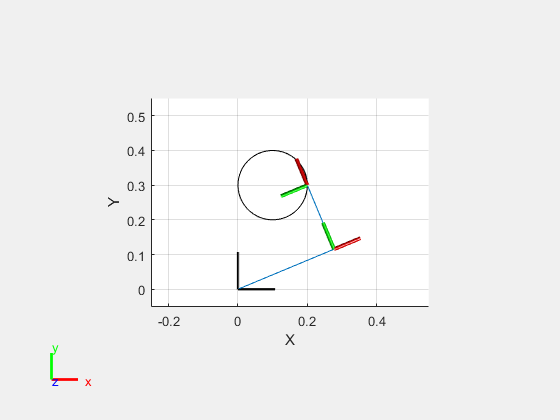

figure
set(gcf,'Visible','on')
show(robot,qs(1,:)');
view(2)
ax = gca;
ax.Projection = 'orthographic';
hold on
plot(points(:,1),points(:,2),'k')
axis ([-0.25 0.55 -0.05 0.55])

framesPerSecond = 15;
r = rateControl(framesPerSecond);
for i = 1:count
    show(robot,qs(i,:)','PreservePlot',false);
    drawnow
    waitfor(r);
end

# Generación de trayectorias con un robot manipulador IRB120

**Cargar robot**

clc;
clear;
close all;
IRB120=loadrobot("abbIrb120",'DataFormat', 'Column', 'Gravity',[0 0 -9.81]);
showdetails(IRB120)

--------------------
Robot: (8 bodies)

 Idx     Body Name            Joint Name            Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------            ----------            ----------     ----------------   ----------------
   1          base        base_link-base                 fixed         base_link(0)   
   2        link_1               joint_1              revolute         base_link(0)   link_2(3)  
   3        link_2               joint_2              revolute            link_1(2)   link_3(4)  
   4        link_3               joint_3              revolute            link_2(3)   link_4(5)  
   5        link_4               joint_4              revolute            link_3(4)   link_5(6)  
   6        link_5               joint_5              revolute            link_4(5)   link_6(7)  
   7        link_6               joint_6              revolute            link_5(6)   tool0(8)  
   8         tool0          joint6-tool0                 fixed            link_6

endEffector = 'tool0';

**Especificaciones de la trayectoria**

Definimos un circulo en el espacio a partir de tres puntos de paso [1] y una orientación del robot fija.

nPts= 50;
t= linspace(0,10,nPts)';
theta= linspace(0,2*pi,nPts)';
radio= 100;
center = [350, 0, 250];

x= (center(1)+ radio*sin(theta))*1e-3;
y= center(2)+radio*cos(theta)*1e-3;
z= center(3)*ones(nPts,1)*1e-3;
waypoints = [x, y, z];
fixOrienation = [pi/2    0   pi/2];
qHome  = homeConfiguration (IRB120);

**Visualización de las trayectoria**

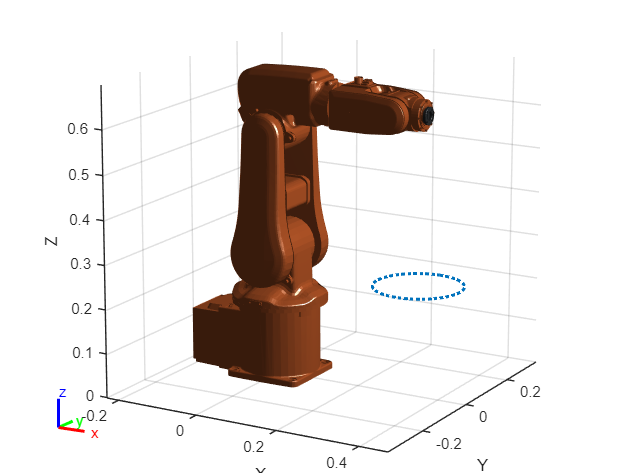

show(IRB120,qHome,'Frames','off','PreservePlot',false);
hold on
plot3(waypoints(:,1),waypoints(:,2),waypoints(:,3),':','LineWidth',2);
axis auto;
view([30 15]);

Si se quiere definr un círculo a partir de tres puntos de paso, se puede utiliza rla función circlefit3d:

*Johannes Korsawe (2023). circlefit3d - fit circle to three points in 3d space (https://www.mathworks.com/matlabcentral/fileexchange/34792-circlefit3d-fit-circle-to-three-points-in-3d-space), MATLAB Central File Exchange. Recuperado April 23, 2023.*

**Solución cinemática inversa y visualización de resultados**

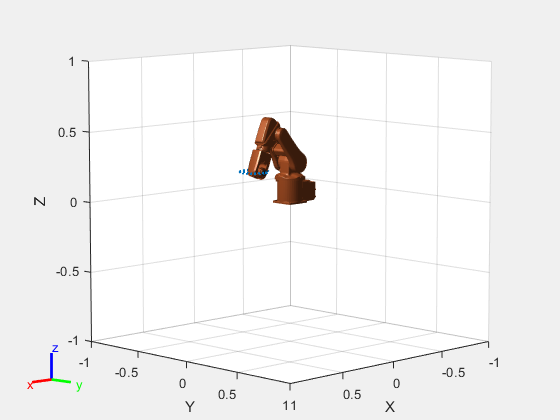

%Define inversekinematics 
ik = inverseKinematics('RigidBodyTree',IRB120);
weights = [1 1 1 1 1 1]';
ikInitGuess = qHome;

%Matrix to save solutions
ndof = length(qHome);
jointWaypoints = zeros(ndof,nPts);

figure
set(gcf,'Visible','on')
show(IRB120,qHome,'Frames','off','PreservePlot',false);
hold all
plot3(waypoints(:,1),waypoints(:,2),waypoints(:,3),':','LineWidth',2);


for i = 1:nPts
    % Solve for the configuration satisfying the desired end effector
    % position
    pose = trvec2tform(waypoints(i,:)) * eul2tform (fixOrienation);
    qSol = ik(endEffector,pose,weights,ikInitGuess);
    jointWaypoints(:,i) = qSol';
    ikInitGuess = qSol;
    show(IRB120, qSol,'Frames','off','PreservePlot',false);
    pause(0.2);
end

**Visualización configuración articular del robot**

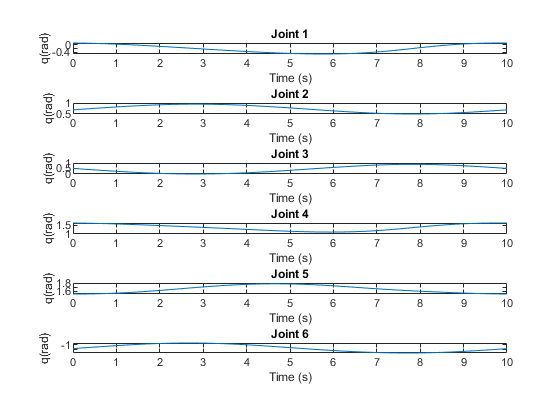

figure
for i=1:ndof
    subplot (ndof,1, i)
    plot (t, jointWaypoints (i,:));
    xlabel ('Time (s)')
    ylabel ('q(rad)')
    title (['Joint ' num2str(i)]);
end  